## Diffrerence equations in Matlab (PSYC 9015 Topic 2). 

This liveScript accompanies class materials for Topic 2. You will 

These excersises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

## Exercise 1. 

In MATLAB use fplot( )to plot different equations of type f(x) = Rx, for R = 2. Type help fplot to see how to use this function.

syms f(x) x
f(x) = 2*x;

figure
fplot(f(x),[-5 5])
hold

Current plot held


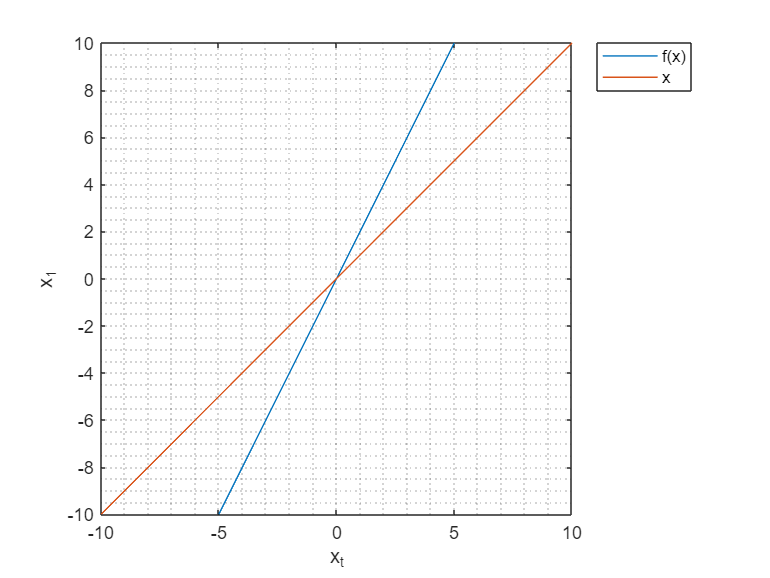

fplot(x)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([-10,10])
xlim([-10,10])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

## *Exercise 2.*

In MATLAB LiveScriptuse f*plot( )*to plot different equations of type *f(x) = Rx, *for different values of R*. *We will add an interactive slider control to achieve that. For example, first define the symbolic function f(x) and variable x. Note that we need to define the symbolic variable *x* to plot the reference 45 degree line. I also implemented a [numeric control slider](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) to vary the values of R.

syms f(x) x
R = -0.5;
f(x) = R*x;

figure
fplot(f(x),[-5 5])
hold

Current plot held


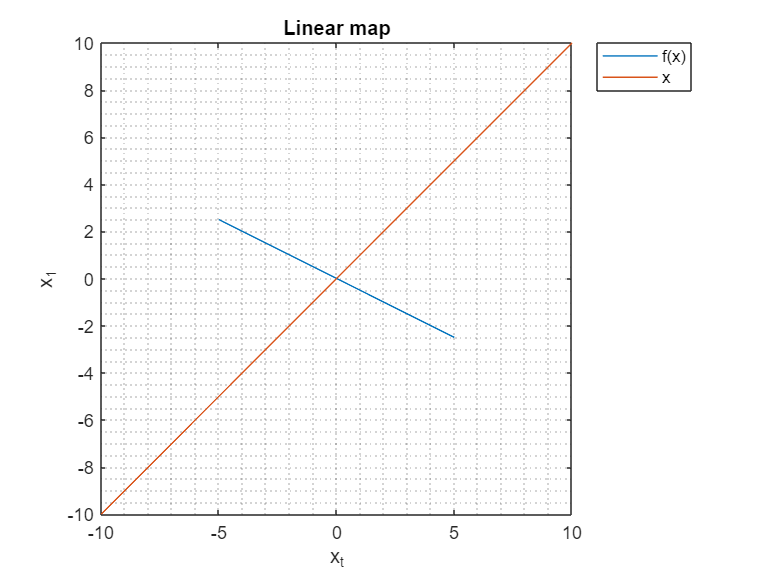

fplot(x)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([-10,10])
xlim([-10,10])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')
title('Linear map')

Now, just for fun, let's plot the logistic map function with the slider for the R parameter. Notice that I changed the range of x and y values to display to be on [0 1].

syms f(x) x
R = 3.99;
f(x) = R*x*(1-x);

figure
fplot(f(x),[0 1])
hold

Current plot held


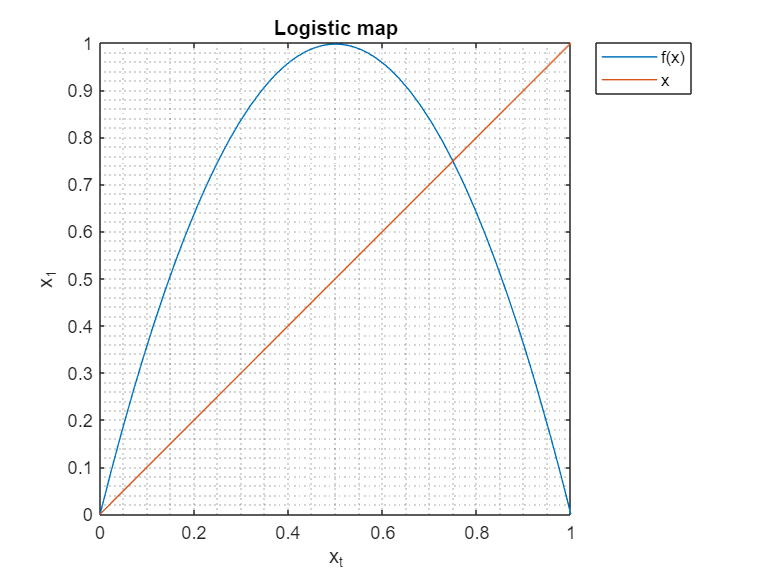

fplot(x)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([0,1])
xlim([0,1])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')
title('Logistic map')

## *Exercise 3. *

In MATLAB write a simple script to iterate and plot *f(x) = **rx**, *for different values of*r (e.g., .5, 1, 1.5, -.5 -1). *For example:

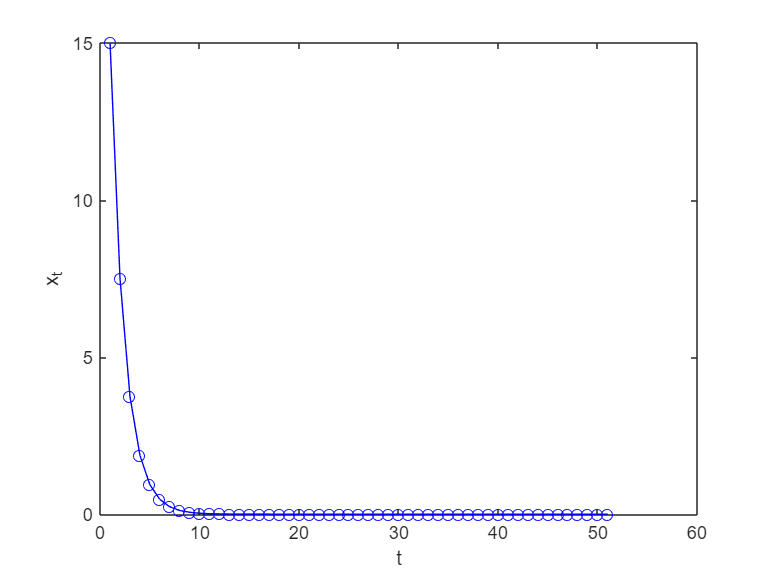

iterations = 50; % set number of iterations
xt = zeros(iterations, 1); % Initialize data array for initial value numerical solution (xt)
xt(1) = 15; % set initial condition
R = 0.5; % set value of parameter R
 
% Calculate numeric solution specific R value and initial condition xt(1)
for i=1:iterations
    xt(i+1) = R*xt(i);
end

figure
plot(xt, 'o-b'); % plot iteration time-series
xlabel('t')
ylabel('x_t')

## Exercise 4.

Use the ***LinearMap.m*** function to numerically iterate *f(x) = rx *and produce a corresponding cobweb plot for the following values of *r: 0.5, 1, 1.5, -.5 -1, -1.5). Remember, you can type help LinearMap to see what the different inputs are!  *For example:

Make sure** LogisticBifurcationDiagram.m** is in your current [Matlab path](https://www.mathworks.com/help/matlab/ref/pwd.html)!

R = 0.5;
LinearMap(30, R, 50, .25);

## Exercise 6. 

Use the **LogisticMap.m** to numerically iterate the logistic map (equation) r*x*(1-x) using the following r values (initial condition of 0.6): 

R = 1.2;
LogisticMap(.6, R, 50, .25);

## Exercise 7. 

Use the **LogisticBifurcationDiagram.m** function procedure to plot the bifurcation diagram of the logistic map. Use the %zoom  tool to explore the different regions of the diagram. Make sure** LogisticBifurcationDiagram.m** is in your current [Matlab path](https://www.mathworks.com/help/matlab/ref/pwd.html). Depending on your computer resrources, it may take a minute to run... 

help LogisticBifurcationDiagram
LogisticBifurcationDiagram(2, 4, .005);

## Exercise 8.

Use the** LogisticMap.m** to test how sensitive the logistic map, r*x*(1-x), is to initial conditions when r = 3.68. For example, examining the iterations time series for the initial conditions 0.6 and 0.601.

LogisticMap(.6, 3.68, 50, .25);
LogisticMap(.601, 3.68, 50, .25);

## Exercise 9. 

Use the *solve* function in MATLAB to solve f(xt+1) = r*xt  for different values of r. For example:

% Define symbolic function f(x) and symbolic variable x
syms f(x) x

% Define parameter R
R = 1.5;
f(x) = R*x;

% Use the solve.m function to determine the intersections between the line
% xt+1 = xt and the graph of f(x) correspond to the fixed point solutions--points where f(x) is equal to x.  
fp = solve(f(x)==x)
help solve
% convert fixed point from symbolic to numeric variable for plotting
fp_num = double(fp); 
% There is only one fixed point here. Let's visualize it.
figure
fplot(f(x),[-5 5])
hold
fplot(x)
plot(fp_num,f(fp_num),'ok') % this line plots the location of the fixed point as (x,y) coordinate. x = fp_num value, y = f(fp_num)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([-10,10])
xlim([-10,10])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

Equivalently, you can also 'substitute' values of R into the function *f(x)* using the *subs.m* function. For example, typing subs(f(x),R,1.2) specifies f(x) with R = 1.2:

% Define symbolic function f(x) and symbolic variable x
syms f(x) x R
f(x) = subs(R*x*(1-x),R,1.5); % function definition and substitution of a specific R-value into f(x)
help subs
% find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x); 

% convert fixed point from symbolic to numeric variable for plotting
fp_num = double(fp) 

## Exercise 11. 

Use the solve  function in MATLAB to solve f(xt+1) = R*xt *(1-x) for different values of R. For example: 

% Define symbolic function f(x) and symbolic variable x
syms f(x) x R
f(x) = subs(R*x*(1-x),R,3.2); 

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp)
% There are two fixed points. Let's visualize them:
figure
fplot(f(x),[0 1])
hold
fplot(x)
plot(fp_num,f(fp_num),'ok') % this line plots the loction of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([0,1])
xlim([0,1])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

## Exercise 13. 

Use fplot.m to plot the *f(x)*= R*x^3 function against the diagonal line xt+1 = xt for different values of r

% Define symbolic function f(x) and symbolic variable x
syms f(x) x R
f(x) = subs(R*x^3,R,1.8); 

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp)

figure
fplot(f(x),[0 1])
hold
fplot(x)
plot(fp_num,f(fp_num),'ok') % this line plots the loction of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([0,1])
xlim([0,1])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

## ***Exercise 14a. ***

Use the ‘diff’ function in MATLAB to find the derivative of *f(**x**t**). *Then substitute *r* and *x**n*** *for different values of R to obtain slope (stability) of fixed points. For example:

% Define symbolic function f(x) and symbolic variable x
syms f(x) x R
f(x) = subs(R*x*(1-x),R,1.1); 

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x))

$$fd(x) = \frac{11}{10}-\frac{11\,x}{5}$$

## Exercise 14b.

Then substitute the values of the fixed points  (x*) into the derivative function obtain slope (m) of f(x) to evaluat stability fixed point(s):

% Find the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp)

fp_num =          0
    0.0909



% substitue the values of the fixed points into the derivative funciton
m = subs(fd(fp_num));
m_num = double(m)

m_num =     1.1000
    0.9000


### The interpretation of the slope values:

- 1 < *m*:   Unstable, exponential growth.

- 0 < *m* < 1:   Stable, monotonic approach to *x*.*

- -1 < *m* < 0:   Stable, oscillatory approach to *x*.*

- *m* < -1:         Unstable, oscillatory growth, aperiodic.

figure
fplot(f(x),[0 1])
hold

Current plot held


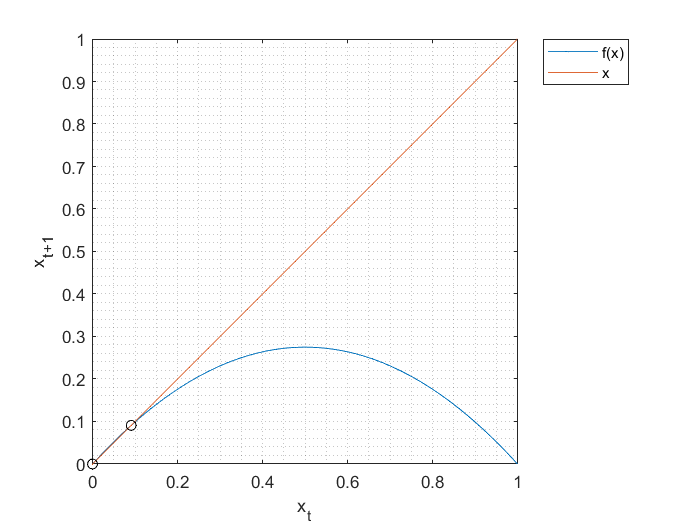

fplot(x)
plot(fp_num,f(fp_num),'ok') % this line plots the loction of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
grid minor
xlabel('x_t')
ylabel('x_t_+_1')
ylim([0,1])
xlim([0,1])
axis square
ylabel('x_t_+_1')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')